# Linear Control Design II - Group Work Problem Module 8

## Description

**Problem 1** Solve Problem 2.10 from the textbook.

**Solution****:**

% Your solution goes here:
clear
syms x1 x2 y kg kr kc k u v Cs Cg
Ta=v;Ts=x1;Tg=x2;y=Tg;
qc=kc*(Ts-Ta),qg=kg*(Ts-Tg),qr=kr*(Ts^4-Ta^4),q=k*u

$$qc = -\mathrm{kc}\,\left(v-x_{1}\right)$$

$$qg = \mathrm{kg}\,\left(x_{1}-x_{2}\right)$$

$$qr = -\mathrm{kr}\,\left(v^{4}-{x_{1}}^{4}\right)$$

$$q = k\,u$$


dx1 = (q-qg-qc-qr)/Cs; dx2 = qg/Cg;
f1(x1,x2,u,v) = dx1; f2(x1,x2,u,v) = dx2;
f(x1,x2,u,v) = [f1;f2]

$$f(x1, x2, u, v) = \left(\begin{array}{c} \frac{\mathrm{kr}\,\left(v^{4}-{x_{1}}^{4}\right)+k\,u+\mathrm{kc}\,\left(v-x_{1}\right)-\mathrm{kg}\,\left(x_{1}-x_{2}\right)}{\mathrm{Cs}}\\ \frac{\mathrm{kg}\,\left(x_{1}-x_{2}\right)}{\mathrm{Cg}} \end{array}\right)$$

g(x1,x2,u,v) = y

$$g(x1, x2, u, v) = x_{2}$$


% Stationary State
syms x10 x20 u0 v0

u0 = solve(f1(x10,x20,u,v0)==0,u)

$$u0 = -\frac{\mathrm{kr}\,\left({v_{0}}^{4}-{x_{10}}^{4}\right)+\mathrm{kc}\,\left(v_{0}-x_{10}\right)-\mathrm{kg}\,\left(x_{10}-x_{20}\right)}{k}$$

x20 = solve(f2(x10,x2,u0,v0)==0,x2)

$$x20 = x_{10}$$

y0 = g(x10,x20,u0,v0)

$$y0 = x_{10}$$


Aa = jacobian(f(x10,x2,u,v),[x10 x2])

$$Aa = \left(\begin{array}{cc} -\frac{4\,\mathrm{kr}\,{x_{10}}^{3}+\mathrm{kc}+\mathrm{kg}}{\mathrm{Cs}} & \frac{\mathrm{kg}}{\mathrm{Cs}}\\ \frac{\mathrm{kg}}{\mathrm{Cg}} & -\frac{\mathrm{kg}}{\mathrm{Cg}} \end{array}\right)$$

Bb = jacobian(f(x1,x2,u,v),[u])

$$Bb = \left(\begin{array}{c} \frac{k}{\mathrm{Cs}}\\ 0 \end{array}\right)$$

Bbv = jacobian(f(x1,x2,u,v0),[v0])

$$Bbv = \left(\begin{array}{c} \frac{4\,\mathrm{kr}\,{v_{0}}^{3}+\mathrm{kc}}{\mathrm{Cs}}\\ 0 \end{array}\right)$$

Cc = jacobian(g(x1,x2,u,v),[x1 x2])

$$Cc = \left(\begin{array}{cc} 0 & 1 \end{array}\right)$$

Dd = jacobian(g(x1,x2,u,v),[u])

$$Dd = 0$$

**Problem 2** Implement a model of the system in the Simulink environment, and use the following numerical values for the model parameters


$$k_c = 0.85 \,W/^{\circ}C \\ k_g = 1.2 \,W/^{\circ}C \\ k_r = 7.8\cdot 10^{-10} \,W/K^4 \\ C_s = 75 \,J/^{\circ}C \\ C_g = 800 \,J/^{\circ}C \\ k = 100 \,W/V$$


The control signal $u$ can assume values in the interval $0-10\,V$.

**Note that you must use absolute temperatures.**

Carry out simulations on the model with the initial values $u_0 = 5\,V$, $T_{si} = 200^{\circ}C$, $T_{gi} = 25^{\circ}C$ and $T_a = 25^{\circ}C$. Determine the stationary state by simulation until all variables have assumed constant values.

**Solution****:**

% Your solution goes here:
kc = 0.85;
kg = 1.2;
kr = 7.8e-10;
Cs = 75;
Cg = 800;
k = 100;

c2k = 273.15;

u0 = 5;
Tsi = 200+c2k;
Tgi = 25+c2k;
Ta = 25+c2k;
x0 = [Tsi Tgi]

x0 =        473.15       298.15


v0 = Ta;

simSwitch = 1;
sCon = simSwitch;
modl = 'Mdl_8';
sim(modl,10000)

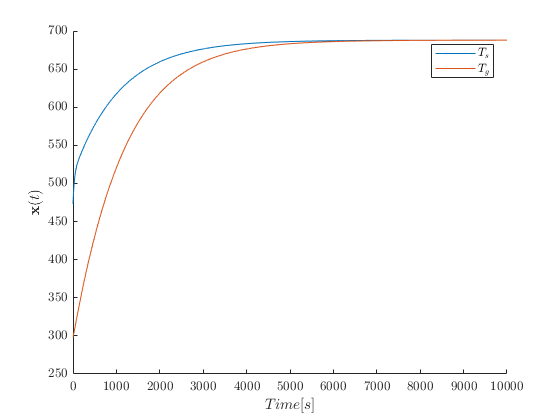

figure
hold on
plot(tout,xout.signals(1).values),xlabel(['$Time [s]$']),ylabel('$\mathbf{x}(t)$')
plot(tout,xout.signals(2).values)
legend('$T_s$','$T_g$')

**Problem 3**  Linearize the nonlinear Simulink model applying the Matlab function `linmod`. Use the function as follows

`[A,B,C,D] = linmod('modelname',x0,u0)`

where $x_0$ and $u_0$ are the stationary states and inputs.

Compare the result with that from the manual linearization from question "c'' in the Problem 2.10.

Find the eigenvalues of the $\mathbf{A}$ matrix by using the Matlab function `eig()`. Repeat the linearization for $u_0 = 2\,V$ and $u_0 = 8\,V$; $T_a = 10^{\circ}C$ and  $T_a = 35^{\circ}C$, and note how the linear model changes with the stationary state. Is the system stable, asymptotically stable or unstable in the different operating conditions?

Remove the radiation effect (set $k_r = 0$) and repeat the linearization for different values $u_0$.

**Solution****:**

% Your solution goes here:
xF = [xFinal.signals(1).values xFinal.signals(2).values];
subsOld = [kc kg kr Cs Cg k x10];
subsNew = [0.85 1.2 7.8e-10 75 800 100 xF(1)];
Aa = eval(subs(Aa,subsOld,subsNew)),...
Bb = eval(subs(Bb,subsOld,subsNew)),...
Cc = eval(subs(Cc,subsOld,subsNew)),...
Dd = eval(subs(Dd,subsOld,subsNew)),...
Bbv = eval(subs(Bbv,subsOld,subsNew));

Aa =      -0.04088        0.016
       0.0015      -0.0015


Bb =        1.3333
            0


Cc =      0     1


Dd =      0


    
simSwitch = -1;
[A,B,C,D] = linmod(modl,xF,u0)

A =      -0.04088        0.016
       0.0015      -0.0015


B =        1.3333
            0


C =      0     1


D =      0


egv = eig(A)

egv =     -0.041481
  -0.00089971



u_array = [2 5 8];
Ta_array = [10 25 35];
Ta_array = Ta_array+c2k;
Tsi = 200+c2k;
Tgi = 25 +c2k;
x0 = [Tsi Tgi];

xouts = zeros(size(xout.signals(1).values,1),18);
xFinals = zeros(9,2); 
egvs = zeros(9,2)';

for i = 1:length(u_array)
    simSwitch = 1;
    u0 = u_array(1);
    for j = 1:length(Ta_array)
        Ta = Ta_array(j);
        v0 = Ta;
        simSwitch = 1;
        sim(modl,10000)
        xouts(:,6*(i-1)+2*j-1) = xout.signals(1).values;
        xouts(:,6*(i-1)+2*j)=xout.signals(2).values;
        xFinals(3*(i-1)+j,:) = [xFinal.signals(1).values xFinal.signals(2).values];
        
        
        simSwitch = -1;
        [A,B,C,D] = linmod(modl,xFinals(i*j,:),u0);
        egvs(:,3*(i-1)+j) = eig(A);
    end
end

f = figure;
cls = ['r','g','b'];

cls = 'rgb'

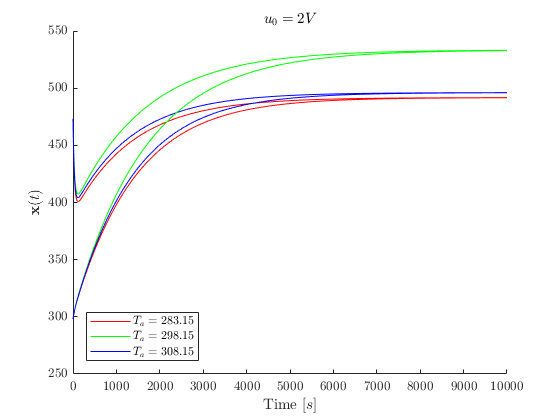

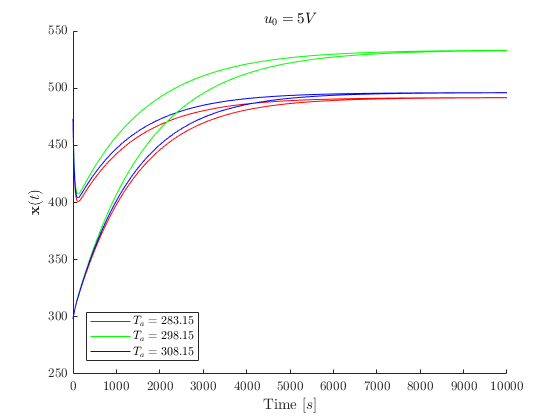

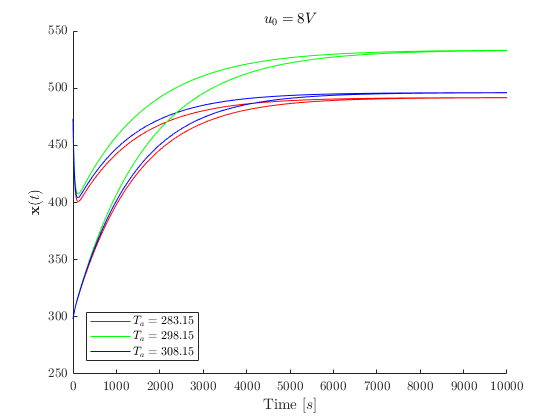

lgd = {['$T_a = ', num2str(Ta_array(1)),'$'];['$T_a = ', num2str(Ta_array(2)),'$'];['$T_a = ', num2str(Ta_array(3)),'$']};
for i = 1:3
    figure
    title(['$u_0 = ' num2str(u_array(i)) 'V$'])
    hold on
    for j = 1:3
        plot(tout,xouts(1,6*(i-1)+2*j-1),cls(j))
    end
    for j = 1:3
        plot(tout,xouts(2,6*(i-1)+2*j),cls(j))
    end
    legend(lgd{1},lgd{2},lgd{3},'Location','southwest')
    xlabel('Time $[s]$'),ylabel('$\mathbf{x}(t)$')
end

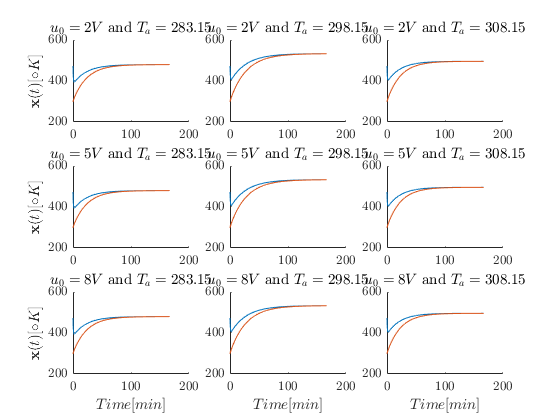

Eigenvals u = 2


ans =     -0.032241    -0.033734    -0.032661
  -0.00071929  -0.00075545   -0.0007298


Eigenvals u = 5


ans =     -0.028231            0    -0.028231
  -0.00060217            0  -0.00060217


Eigenvals u = 8


ans =             0            0    -0.033169
            0            0  -0.00074217


disp('Eigenvals u = 2'),egvs(:,1:3),disp('Eigenvals u = 5'),egvs(:,4:6),disp('Eigenvals u = 8'), egvs(:,7:9),

xouts = zeros(size(xout.signals(1).values,1),12);
xFinals = zeros(6,2); 
egvs = zeros(6,2)';

for i = 1:length(u_array)
    simSwitch = 1;
    u0 = u_array(1);
    for j = 1:2
        if j == 2
            kr = 0;
        else
            kr = 7.8e-10;
        end
        Ta = Ta_array(2);
        v0 = Ta;
        simSwitch = 1;
        sim(modl,10000)
        xouts(:,4*(i-1)+2*j-1) = xout.signals(1).values;
        xouts(:,4*(i-1)+2*j)=xout.signals(2).values;
        xFinals(2*(i-1)+j,:) = [xFinal.signals(1).values xFinal.signals(2).values];
        
        
        simSwitch = -1;
        [A,B,C,D] = linmod(modl,xFinals(i*j,:),u0);
        egvs(:,2*(i-1)+j) = eig(A);
    end
end

for i = 1:length(u_array)
    figure
    hold on
    title(['$u_0 = ' num2str(u_array(i)) 'V$'])
    for j = 1:2
        plot(tout,xouts(1,4*(i-1)+2*j-1),cls(j))
    end
    for j =1:2
        plot(tout,xouts(1,4*(i-1)+2*j-1),cls(j))
    end
    legend(['$k_r = ' num2str(7.8e-10) '$'], ['$k_r = 0$'])
end
disp('Eigenvals u=2,5,8 | kr = 7.8e-10'),egvs(:,1:3),disp('Eigenvals u=2,5,8 | kr = 0'),egvs(:,4:6)

